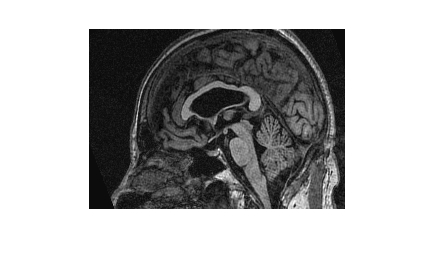

%Load MR data
data = load("mr.mat");

MR1 = data.mr1;
MR2 = data.mr2;

imshow(MR1, []);

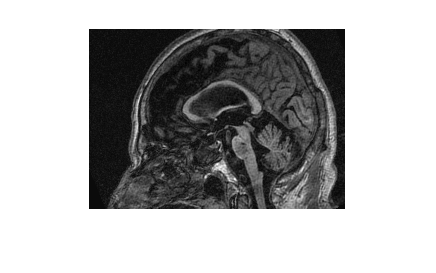

imshow(MR2, []);

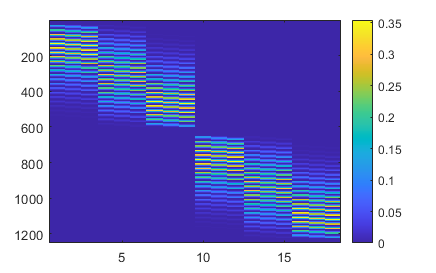

%Obtain the 2D tensor B-spline matrix
m = [25 25];
Q = TwoDTensorSpline(m, 3);
imagesc(Q);
colorbar;

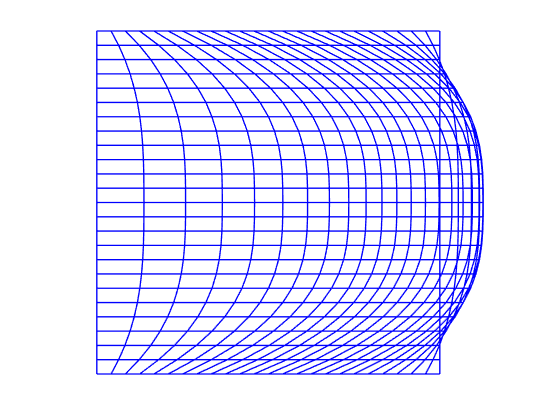

%Deform grid along X-axis
w1 = 10 * ones(9, 1);
w2 = zeros(9, 1);
w = [w1;w2];
[y1, y2] = DeformGrid(m, w, Q);
figure();
plotgrid(y1, y2);

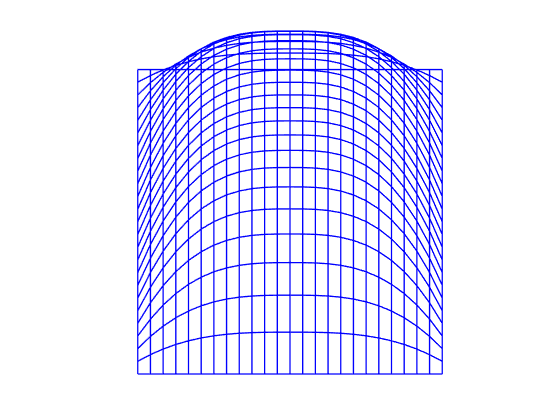


%Deform grid along Y-axis
w = [w2;w1];
[y1, y2] = DeformGrid(m, w, Q);
figure();
plotgrid(y1, y2);

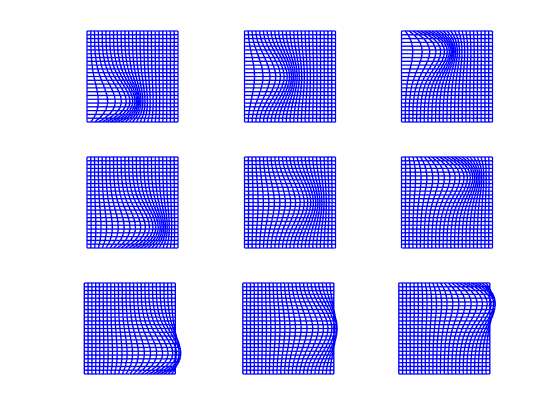


%Deform along X-axis with respect to every individual 2D basis function
figure();
for i = 1:9
    w = zeros(18, 1);
    w(i) = 15;
    [y1, y2] = DeformGrid(m, w, Q);
    subplot(3, 3, i);
    plotgrid(y1, y2);
end

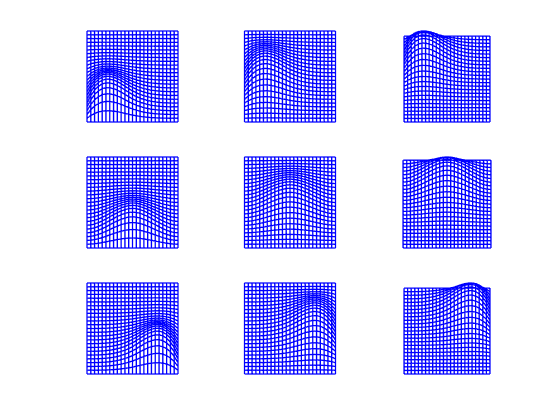


%Deform along Y-axis with respect to every individual 2D basis function
figure();
for i = 1:9
    w = zeros(18, 1);
    w(9 + i) = 15;
    [y1, y2] = DeformGrid(m, w, Q);
    subplot(3, 3, i);
    plotgrid(y1, y2);
end